# **YOLO**

***YOLO (You Only Look Once) ***é um algoritmo de detecção de objetos em tempo real. Os autores do algoritmo colocam o problema da detecção como regressão, com separação espacial usando *bounding boxes* e probabilidade associada por meio de uma única rede neural de convolução (*convolutional neural network - CNN*)

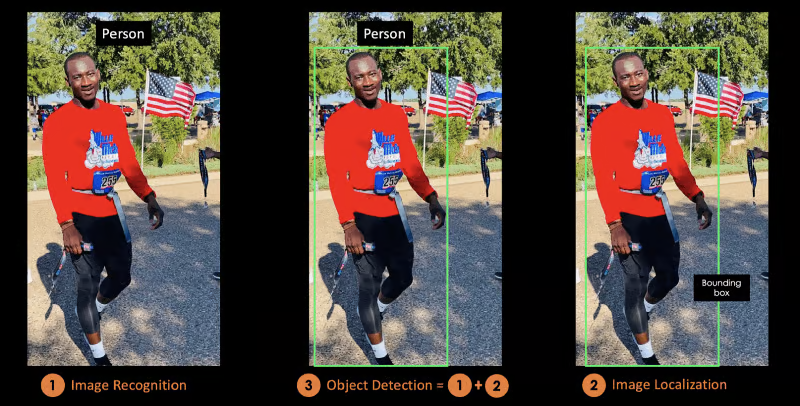

Algumas vantagens de uso do YOLO são:

- Rapidez, tendo a capacidade de processar a 45 FPS, ainda mais atingindo precisão média mais alta que outros sistemas de tempo real.

- Acurácia

- Generalização, permitindo detecção rápida e robusta de objetos.

#### >> Funcionamento do YOLO

Suponhamos que queiramos identificar jogadores e a bola em um jogo de futebol.

- Blocos Residuais: Em um primeiro instante, o algoritmo divide a imagem original em NxN células de tamanho igual. 

- Regressão das *Bounding Boxes*: O próximo passo é determinar as *bounding boxes* correspondentes aos retângulos que possuem os objetos de interesse na imagem. O algoritmo define os atributos das *bboxes* usando um único módulo de regressão no formato:

Y = [pc,bx,by,bh,bw,c1,c2]

            Onde `pc` corresponde à probabilidade de cada grid conter o objeto.

            `bx,by `são as coordenadas `x,y` do centro da *bbox* correspondente

            `bh,bw` são a altura e largura do *bbox* correspondente

            `c1,c2` correspondem às duas classes, *jogador e bola*.

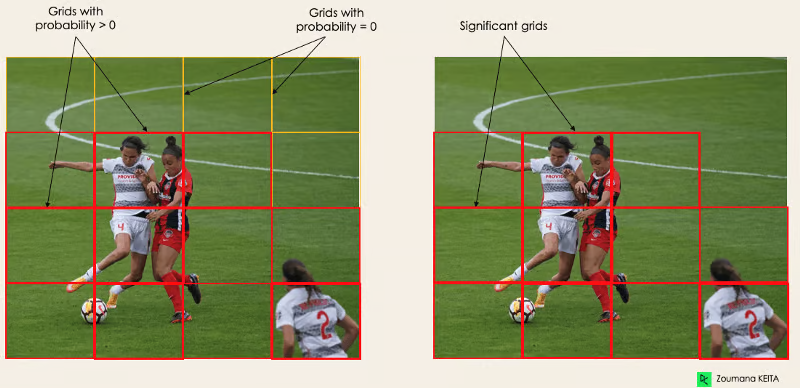

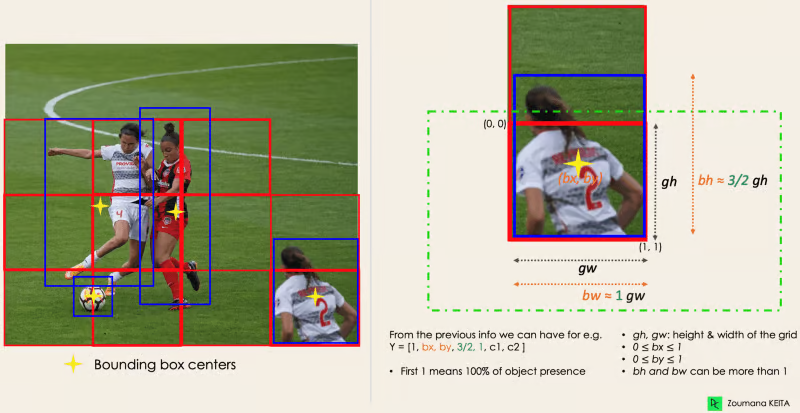

Tal vetor é gerado pelas camadas convolucionais da rede de convolução.

3. Muitas vezes, um objeto tem inúmeros candidatos à predição. É possível definir um *threshold* que descarta as *bboxes* que são irrelevantes por meio de IoU. O algoritmo vai descartar as *bboxes* com IoU menor que o limitante definido.

4. Um último recurso, em caso das *bboxes* todas terem score maior que o *threshold*, é o NMS (*Non Max Suppression*). No caso, é escolhido a caixa de referência com maior confiança, calculada pelo IoU.

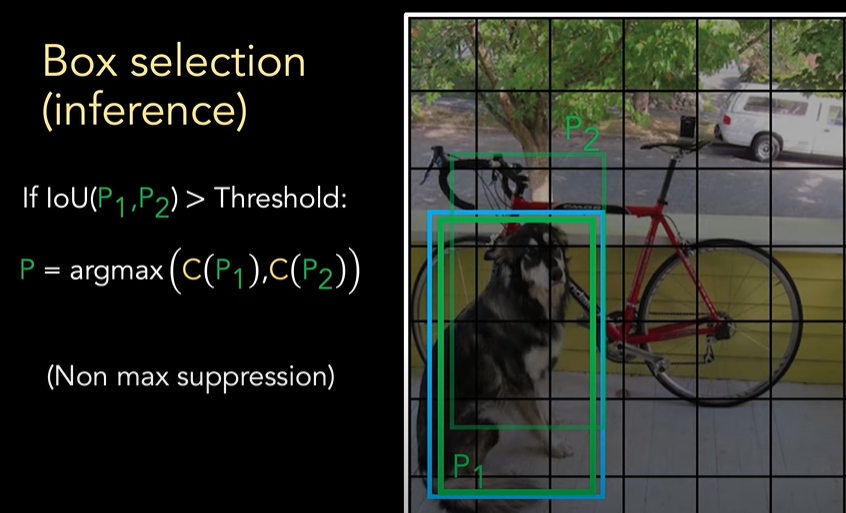

#### >> Geração do Ground Truth Data

[https://www.mathworks.com/help/vision/use-ground-truth-object.html?s_tid=CRUX_lftnav](https://www.mathworks.com/help/vision/use-ground-truth-object.html?s_tid=CRUX_lftnav) 

[https://www.mathworks.com/help/vision/ug/share-and-store-labeled-ground-truth-data.html](https://www.mathworks.com/help/vision/ug/share-and-store-labeled-ground-truth-data.html) 

O primeiro passo para treinar o modelo é criando um *dataset*, o qual será o conjunto de imagens, rótulos e caixas de representação que formam o *ground truth data*.

Tal conjunto pode ser obtido pronto usando o **Roboflow Universe, Kaggle** ou **Google Imagens V7**, ou construído usado **Label Studio** ou o **Image Labeler **do MATLAB.

A partir do Image Labeler App, é possível gerar um arquivo externo em extensão .mat que possui um objeto no formato `gTruth`. Este possui os caminhos para as imagens, os *labels* e as posições das *bounding boxes*.

- É possível compartilhar esse objeto

- Pode ser usado para treinar algoritmos

- Pode ser usado para validar algoritmos

Para poder compartilhar o arquivo, é preciso ir para **Export Labels > To File. **Além de compartilhar as extensões .mat, é preciso compartilhar as fontes de dados (imagens). Ao compartilhar os `gTruth`, o arquivo vai referenciar-se às imagens com diretórios absolutos, o que vai causar problemas ao mudar os arquivos de lugar. Pode-se resolver isso usando o `changeFilePaths`

alternativePaths = ["C:\Shared\ImgFolder" "D:\Shared\ImgFolder"];
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);

Se os nomes também mudaram, você pode mudar nome por nome

alternativePaths =  ...
    {["C:\Shared\ImgFolder\Img1.png" "D:\Shared\ImgFolder\Img1_new.png"], ...
     ["C:\Shared\ImgFolder\Img2.png" "D:\Shared\ImgFolder\Img2_new.png"], ...
     .
     .
     .
     ["C:\Shared\ImgFolder\ImgN.png" "D:\Shared\ImgFolder\ImgN_new.png"]};
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);

Um outro problema que pode surgir é de vários `Ground Truth Data `advindos de várias fontes, para resolver isso, pode-se usar o comando `merge`.

`gTruth = merge(gTruth1, gTruth2, ..., gTruthN)`

`gTruth = merge(_____,OutputFolder=name)`

Exemplo do gTruthDepthV1.

data = load("C:\Users\Pedro\Desktop\Dados\gTruthDepthV1.mat")

% Lista original de caminhos antigos (como cell array de strings)
caminhosAntigos = {
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185333.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185351.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185418.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185432.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185448.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185504.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185543.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185554.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185607.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185621.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185724.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185742.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185755.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185808.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185821.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185834.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185851.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185906.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185920.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185932.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 185945.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190032.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190047.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190100.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190113.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190125.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190141.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190202.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190236.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190251.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190337.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190352.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190405.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190417.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190431.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190446.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190458.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190511.png'
    'C:\Users\Pedro\Downloads\imagens profundidade\imagens profundidade\Captura de tela 2025-04-29 190525.png'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (6).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.52.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (5).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (3).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (4).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (2).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51 (1).jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.32.51.jpeg'
    'C:\Users\Pedro\Downloads\WhatsApp Image 2025-04-30 at 00.31.38.jpeg'
};

% Novo diretório
novoDiretorio = 'C:\Users\Pedro\Desktop\Dados';

% Inicializa o cell array de pares
alternativePaths = cell(size(caminhosAntigos));

% Gera o vetor com [caminho_antigo caminho_novo]
for i = 1:numel(caminhosAntigos)
    caminhoAntigo = caminhosAntigos{i};
    [~, nomeArquivo, ext] = fileparts(caminhoAntigo);
    caminhoNovo = fullfile(novoDiretorio, [nomeArquivo ext]);
    alternativePaths{i} = [string(caminhoAntigo), string(caminhoNovo)];
end

% Altere os caminhos do groundTruth
unresolvedPaths = changeFilePaths(data.gTruth, alternativePaths);
